# P4.1

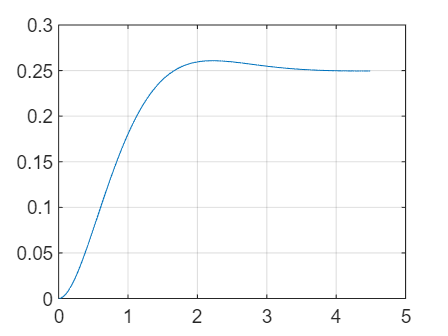


A = [1 -2; 0.5 -1];
B = [2;2];
C = [-1 1];
D = 0;
K = [-5.414 6.828];
AK = A-B*K;
[y,x,t] = step(AK,B,C,D);
plot(t,y)
grid on

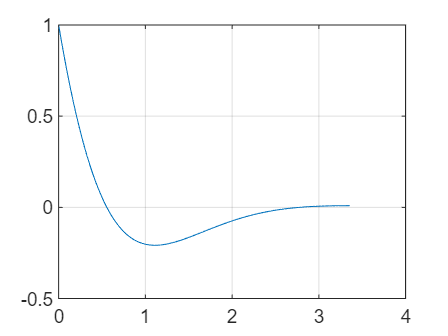

[u,x,t] = step(AK,B,-K,D);
plot(t,u+1)
grid on

## P4.2

B = [4.1;2];
Mc = ctrb(A,B)

Mc =     4.1000    0.1000
    2.0000    0.0500


det(Mc)

ans = 0.0050

% controllable
ev = [-2^0.5+1i*2^0.5 -2^0.5-1i*2^0.5];
K = acker(A,B,ev)

K = 	1.0e+03 *

   -1.5717    3.2234


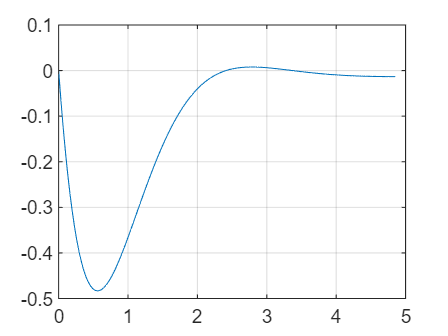

AK2 = A-B*K;
[y,x,t] = step(AK2,B,C,D);
plot(t,y)
grid on

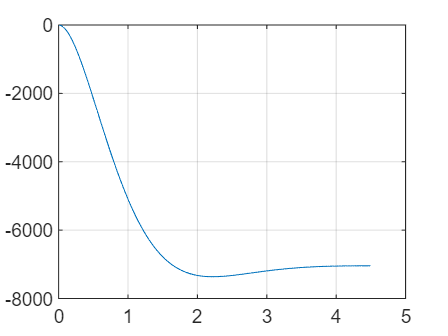

[u,x,t] = step(AK,B,-K,D);
plot(t,u+1)
grid on

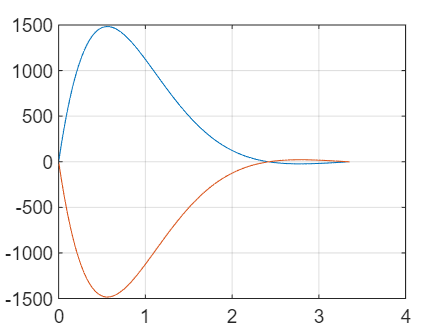

[u,x,t] = step(AK2,B,-K,D);
plot(t,-K(1)*x(:,1),t,-K(2)*x(:,2))
grid on

## P4.4

Ts = 0.2;
F = [-2 -3 5;
    -0.875 0.5 1;
    -1.875 -0.5 3];
G = [0;1;1];
lambda = eig(F)

lambda =    0.5000 + 1.0000i
   0.5000 - 1.0000i
   0.5000 + 0.0000i


Mc = ctrb(F,G);
det(Mc)

ans = 1

p = poly(lambda)

p =     1.0000   -1.5000    1.7500   -0.6250


lambda_lreq = [-2 -2+1i -2-1i];
lambda_dreq = exp(lambda_lreq*Ts)

lambda_dreq =    0.6703 + 0.0000i   0.6570 + 0.1332i   0.6570 - 0.1332i


r = poly(lambda_dreq)

r =     1.0000   -1.9842    1.3301   -0.3012


## P4.6

A = [0 1 0;
    0 -0.2 300;
    0 -700 -4.667];
B = [0;0;93.33];
Bv = [0;2;0];
C = [1 0 0];
ev = [-20 -12+1i*12 -12-1i*12];
K = acker(A,B,ev)

K =     0.2057   -7.4732    0.4193


AK = A-B*K;
% d)
A1 = [A zeros(3,1); -C 0];
B1 = [B;0];
Br = [0;0;0;1];
Bv1 = [Bv;0];
C1 = [C 0];
evri = [ev -16];
K1 = acker(A1,B1,evri);

K1 =     0.6446   -7.4481    0.5907   -3.2915


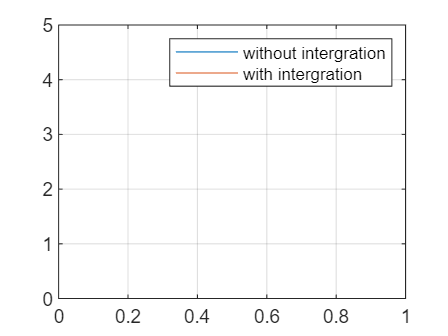

AK1 = A1-B1*K1;
% f)
t = 0:0.01:1;
% without intergration
[y,x] = step(AK,B,C,0,1,t);
% with intergration'
[y1,x1] = step(AK1,Br,C1,0,1,t);
plot(t,y,t,y1)
legend('without intergration','with intergration')
grid on

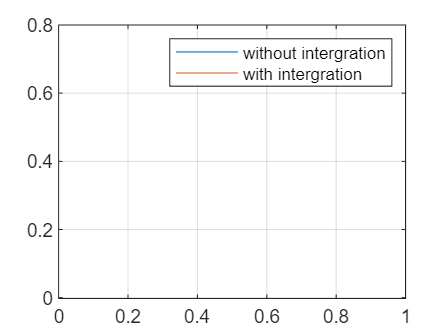

% with v0 = 50
[yf,xf] = step(AK,Bv,C,0,1,t);
[yf1,xf1] = step(AK1,Bv1,C1,0,1,t);
plot(t,50*yf,t,50*yf1)
grid on
legend('without intergration','with intergration')

## 4.8

A = [0 1;-2 2];
B = [0;1];
C = [0 3];
D = 0;
[num,den] = ss2tf(A,B,C,D)

num =      0     3     0


den =     1.0000   -2.0000    2.0000


G = tf(num,den)

G =
 
       3 s
  -------------
  s^2 - 2 s + 2
 
Continuous-time transfer function.



Q = [-6 0;0 3];
Q_inv = inv(Q);
Aoc = Q*A*Q_inv

Aoc =      0    -2
     1     2


Boc = Q*B

Boc =      0
     3


Coc = C*Q_inv

Coc =      0     1


## 4.10

A = [0 1; -404.8 -29.33];
eig(A)

ans =  -14.6650 +13.7745i
 -14.6650 -13.7745i


damp(A)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -1.47e+01 + 1.38e+01i     7.29e-01       2.01e+01          6.82e-02    
 -1.47e+01 - 1.38e+01i     7.29e-01       2.01e+01          6.82e-02    


dcgain